chromosome_of_interest = 'chr2';
TF_of_interest = 'CTCF';
load_name = strcat(TF_of_interest, '_', chromosome_of_interest, '_positions');
load(load_name)
merged_data

merged_data =            1       11484           1         -14           0
           1       11543           1          -9           1
           1       11601           1          -5           1
           1       11660           1          -9           1
           1       11662           0         -14           0
           1       11725           1         -13           1
           1       11784           1         -15           0
           1       11796           0         -13           1
           1       11852           1         -13           1
           1       11924           1          -7           1


first_order = strcat(chromosome_of_interest, 'shapes');
second_order = strcat(chromosome_of_interest, 'shapes2');
tic
load(first_order)
load(second_order)
toc

Elapsed time is 34.532375 seconds.


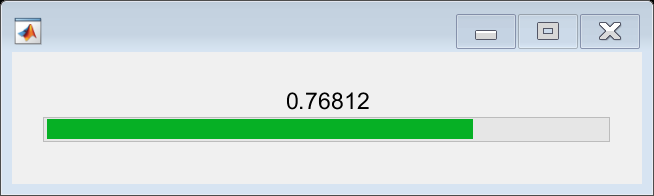

x_data = [];
y_data = [];

success = false;
x = 1;

loading = waitbar(0,'Please wait...');
tic
%length(merged_data)
for i=1:length(merged_data)
    r = i/length(merged_data);
    progress = round(r,5);
    waitbar(progress,loading,string(progress));
 
    if merged_data(i,2)-3 > length(initial)
        break;
    end
    if merged_data(i,2)-3 > length(initial2)
        break;
    end
    C = initial(merged_data(i,2)-3, :);
    C2 = initial2(merged_data(i,2)-3, :);
            
    if merged_data(i,3) == 1
        x_data = [x_data; C C2 merged_data(i, 3) merged_data(i, 4)];
        y_data = [y_data; merged_data(i, 5)];
    else
        C = C';
        idx = reshape(flipud(reshape(1:88,22,4)),1,88);
        C = C(idx,:);
        C = C';
        
        C2 = C2';
        idx = reshape(flipud(reshape(1:88,22,4)),1,88);
        C2 = C2(idx,:);
        C2 = C2';
        
        x_data = [x_data; C C2 merged_data(i, 3) merged_data(i, 4)];
        y_data = [y_data; merged_data(i, 5)];
    end
end

toc

Elapsed time is 2.491751 seconds.



x_data

x_data =     5.2200    4.9500    4.7300    4.8400    4.4600    4.0300    4.5800    4.7500    4.6200    4.8500    5.5200    5.1600    4.6100    4.9400    5.4500    5.7800    5.7800    5.7000    4.8200    4.3600    5.1600    5.1900   -2.9200   -2.5600   -4.3900   -9.9100  -10.0800   -7.6800   -2.3700   -1.0300   -1.3200   -0.1400   -5.9200   -3.6000   -1.4700   -8.6300   -9.9000   -3.8000   -3.8000  -10.7500   -4.1400   -7.9700   -5.0300   -3.2600    3.9700   -1.8400   -1.2600   -1.3700   -3.8000   -3.8800
    4.9800    5.3000    5.8800    5.7100    5.4100    4.9600    4.8200    4.6200    4.4200    4.6500    5.4500    5.0800    5.2700    5.5300    5.4300    4.9300    4.9300    5.4600    5.3100    5.1100    5.1300    5.6900   -4.5200   -7.6800   -4.1300   -3.9400   -3.3900   -2.8900   -2.1300   -1.3200   -0.1400   -9.1600   -9.9000   -3.3600   -1.7200   -5.8700   -3.3400   -2.5400   -2.5400   -4.0300   -7.4000   -4.2400   -7.4400   -6.5100   -1.5000   -2.9600    3.0000   -0.6600    3.2000

y_data

y_data =      0
     1
     1
     1
     0
     1
     0
     1
     1
     1


Arr = [x_data y_data]

Arr =     5.2200    4.9500    4.7300    4.8400    4.4600    4.0300    4.5800    4.7500    4.6200    4.8500    5.5200    5.1600    4.6100    4.9400    5.4500    5.7800    5.7800    5.7000    4.8200    4.3600    5.1600    5.1900   -2.9200   -2.5600   -4.3900   -9.9100  -10.0800   -7.6800   -2.3700   -1.0300   -1.3200   -0.1400   -5.9200   -3.6000   -1.4700   -8.6300   -9.9000   -3.8000   -3.8000  -10.7500   -4.1400   -7.9700   -5.0300   -3.2600    3.9700   -1.8400   -1.2600   -1.3700   -3.8000   -3.8800
    4.9800    5.3000    5.8800    5.7100    5.4100    4.9600    4.8200    4.6200    4.4200    4.6500    5.4500    5.0800    5.2700    5.5300    5.4300    4.9300    4.9300    5.4600    5.3100    5.1100    5.1300    5.6900   -4.5200   -7.6800   -4.1300   -3.9400   -3.3900   -2.8900   -2.1300   -1.3200   -0.1400   -9.1600   -9.9000   -3.3600   -1.7200   -5.8700   -3.3400   -2.5400   -2.5400   -4.0300   -7.4000   -4.2400   -7.4400   -6.5100   -1.5000   -2.9600    3.0000   -0.6600    3.2000   


save_name = strcat(TF_of_interest, '_', chromosome_of_interest, '_data');
save(save_name, 'Arr')


Arr = [x_data y_data]

Arr =     5.2200    4.9500    4.7300    4.8400    4.4600    4.0300    4.5800    4.7500    4.6200    4.8500    5.5200    5.1600    4.6100    4.9400    5.4500    5.7800    5.7800    5.7000    4.8200    4.3600    5.1600    5.1900   -2.9200   -2.5600   -4.3900   -9.9100  -10.0800   -7.6800   -2.3700   -1.0300   -1.3200   -0.1400   -5.9200   -3.6000   -1.4700   -8.6300   -9.9000   -3.8000   -3.8000  -10.7500   -4.1400   -7.9700   -5.0300   -3.2600    3.9700   -1.8400   -1.2600   -1.3700   -3.8000   -3.8800
    4.9800    5.3000    5.8800    5.7100    5.4100    4.9600    4.8200    4.6200    4.4200    4.6500    5.4500    5.0800    5.2700    5.5300    5.4300    4.9300    4.9300    5.4600    5.3100    5.1100    5.1300    5.6900   -4.5200   -7.6800   -4.1300   -3.9400   -3.3900   -2.8900   -2.1300   -1.3200   -0.1400   -9.1600   -9.9000   -3.3600   -1.7200   -5.8700   -3.3400   -2.5400   -2.5400   -4.0300   -7.4000   -4.2400   -7.4400   -6.5100   -1.5000   -2.9600    3.0000   -0.6600    3.2000   

col1 = Arr(:, 1);
Arr = Arr(col1~=0, :)

Arr =     5.2200    4.9500    4.7300    4.8400    4.4600    4.0300    4.5800    4.7500    4.6200    4.8500    5.5200    5.1600    4.6100    4.9400    5.4500    5.7800    5.7800    5.7000    4.8200    4.3600    5.1600    5.1900   -2.9200   -2.5600   -4.3900   -9.9100  -10.0800   -7.6800   -2.3700   -1.0300   -1.3200   -0.1400   -5.9200   -3.6000   -1.4700   -8.6300   -9.9000   -3.8000   -3.8000  -10.7500   -4.1400   -7.9700   -5.0300   -3.2600    3.9700   -1.8400   -1.2600   -1.3700   -3.8000   -3.8800
    4.9800    5.3000    5.8800    5.7100    5.4100    4.9600    4.8200    4.6200    4.4200    4.6500    5.4500    5.0800    5.2700    5.5300    5.4300    4.9300    4.9300    5.4600    5.3100    5.1100    5.1300    5.6900   -4.5200   -7.6800   -4.1300   -3.9400   -3.3900   -2.8900   -2.1300   -1.3200   -0.1400   -9.1600   -9.9000   -3.3600   -1.7200   -5.8700   -3.3400   -2.5400   -2.5400   -4.0300   -7.4000   -4.2400   -7.4400   -6.5100   -1.5000   -2.9600    3.0000   -0.6600    3.2000   


save_name = strcat(TF_of_interest, '_', chromosome_of_interest, '_data');
save(save_name, 'Arr')


TF_of_interest = 'CTCF';

load_name = strcat(TF_of_interest, '_chr1_data');

chr1_data = load(load_name)

chr1_data = struct with fields:
    Arr: [1540×179 double]



load_name = strcat(TF_of_interest, '_chr2_data');

chr2_data = load(load_name)

chr2_data = struct with fields:
    Arr: [370×179 double]



Arr = [chr1_data.Arr; chr2_data.Arr]

Arr =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400   -8.1200   -8.3000   -3.7400   -3.6800   -6.7600   -1.7200   -3.7900   -7.8900   -7.0000   -4.4400   -5.5400   -1.6800   -6.6400   -7.1100   -4.0300   -2.9800   -3.2000   -6.7600   -1.7200   -3.6000   -6.6900   -3.0600   -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400   -0.8800   -6.3800   -3.0600   -6.6900   -3.6000   -1.7200   -6.7600   -3.2000   -2.9800   -4.0300   -7.1100   -6.6400   -1.6800   -5.5400   -4.4400   -7.0000   -7.8900   -3.7900   -1.7200   -6.7600   -3.6800   -3.7400   -1.0600   -1.5000    3.9300   -2.1200   -1.9800   


save_name = strcat(TF_of_interest, '_chr1_2_data');
save(save_name, 'Arr')

Arr =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400   -8.1200   -8.3000   -3.7400   -3.6800   -6.7600   -1.7200   -3.7900   -7.8900   -7.0000   -4.4400   -5.5400   -1.6800   -6.6400   -7.1100   -4.0300   -2.9800   -3.2000   -6.7600   -1.7200   -3.6000   -6.6900   -3.0600   -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400   -0.8800   -6.3800   -3.0600   -6.6900   -3.6000   -1.7200   -6.7600   -3.2000   -2.9800   -4.0300   -7.1100   -6.6400   -1.6800   -5.5400   -4.4400   -7.0000   -7.8900   -3.7900   -1.7200   -6.7600   -3.6800   -3.7400   -1.0600   -1.5000    3.9300   -2.1200   -1.9800   

Arr =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400   -8.1200   -8.3000   -3.7400   -3.6800   -6.7600   -1.7200   -3.7900   -7.8900   -7.0000   -4.4400   -5.5400   -1.6800   -6.6400   -7.1100   -4.0300   -2.9800   -3.2000   -6.7600   -1.7200   -3.6000   -6.6900   -3.0600   -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400   -0.8800   -6.3800   -3.0600   -6.6900   -3.6000   -1.7200   -6.7600   -3.2000   -2.9800   -4.0300   -7.1100   -6.6400   -1.6800   -5.5400   -4.4400   -7.0000   -7.8900   -3.7900   -1.7200   -6.7600   -3.6800   -3.7400   -1.0600   -1.5000    3.9300   -2.1200   -1.9800   

Arr_MGW =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400  -13.0000    1.0000
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400  -10.0000    1.0000
    4.8200    4.5100    4.6500    5.4500    5.0800    5.2700    5.7400    5.6700    4.9400    4.1800    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200  -11.0000    1.0000
    5.1500    4.8200    4.6300    5.1800    5.4100    4.9600    4.8200    4.7500    4.8900    5.4400    5.3100    4.6500    4.4200    4.7300    5.0200    5.3300    5.3800    4.6600    3.9000    4.5200    4.5000    4.6700  -14.0000         0
    5.3200    5.9400    5.

x_data_MGW =     5.3200    4.3700    4.8200    5.1500    5.3200    4.3700    4.8200    4.6300    5.0900    5.6100    5.4300    5.0300    5.5400    5.0200    5.3600    5.5100    4.4500    4.7700    4.7800    4.8000    5.5400    4.7800    4.9800    5.7400    5.2500    5.4100    5.4500    4.3700    5.1000    4.8000    4.9500    5.0800    4.6500    4.4200    3.6400    5.5400    5.7100    5.6700    5.2900    5.0200    4.9800    4.9300    4.7700    4.6700    4.7300    4.7200    4.7700    4.7800    4.7800    4.8500
    5.9400    4.9700    4.5100    4.8200    5.9400    4.9700    4.5100    4.5100    4.8600    6.1100    5.5300    4.8100    5.1800    5.6600    4.8300    5.3000    4.2900    4.8200    4.7300    5.3100    5.4100    5.3000    5.3200    5.3400    5.7400    5.6700    4.9400    4.9300    5.0500    4.9700    5.3100    5.4200    5.4500    4.3700    4.3700    4.5900    5.2500    5.6700    4.9600    5.0500    4.3600    5.4400    4.9600    5.4000    4.8500    4.9400    5.5600    4.9700    4.

Arr_avg =     5.0921    5.0683    5.0174    5.1419    5.1418    4.9985    5.1008    5.1208    4.8613    4.9334    5.1814    4.9859    5.0025    5.3288    5.2028    5.0114    5.1723    5.1987    5.0130    5.0568    5.1188    5.0678


positive_data_MGW =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400  -13.0000    1.0000
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400  -10.0000    1.0000
    4.8200    4.5100    4.6500    5.4500    5.0800    5.2700    5.7400    5.6700    4.9400    4.1800    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200  -11.0000    1.0000
    5.3200    5.9400    5.8800    5.5900    5.3700    5.1700    5.6600    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400  -10.0000    1.0000
    4.3700    4.

negative_data_MGW =     5.1500    4.8200    4.6300    5.1800    5.4100    4.9600    4.8200    4.7500    4.8900    5.4400    5.3100    4.6500    4.4200    4.7300    5.0200    5.3300    5.3800    4.6600    3.9000    4.5200    4.5000    4.6700  -14.0000         0
    4.6300    4.5100    4.7700    5.4100    5.7100    5.8800    5.5600    4.7700    4.2900    4.4200    4.6500    5.1900    5.2000    5.8400    6.0100    5.3900    4.7000    4.7000    5.3900    6.0100    5.8400    5.3200  -14.0000         0
    5.4300    5.5300    5.1300    5.1800    5.4100    5.0600    5.4300    5.5300    4.8000    4.8000    5.6700    5.7900    5.7900    5.6700    4.9500    4.6100    4.8200    4.9400    5.1900    5.3600    4.9600    4.9600  -14.0000         0
    5.0300    4.8100    4.5600    5.2800    5.4000    4.7700    4.8500    4.9300    4.8500    4.9300    5.4100    5.3100    5.1100    5.1300    5.6700    5.2200    5.1500    5.0800    4.9200    5.4000    6.0100    4.8900  -13.0000         0
    5.5400    5.

positive_col =     5.3200
    4.3700
    4.8200
    5.3200
    4.3700
    4.8200
    5.0900
    5.6100
    5.0200
    5.3600


most_common_positive = 4.9500

mean_positive = 5.1223

std_positive = 0.4184

negative_col =     5.1500
    4.6300
    5.4300
    5.0300
    5.5400
    4.7700
    4.9800
    5.7400
    5.2500
    5.4500


most_common_negative = 4.9500

mean_negative = 5.0601

std_negative = 0.4164

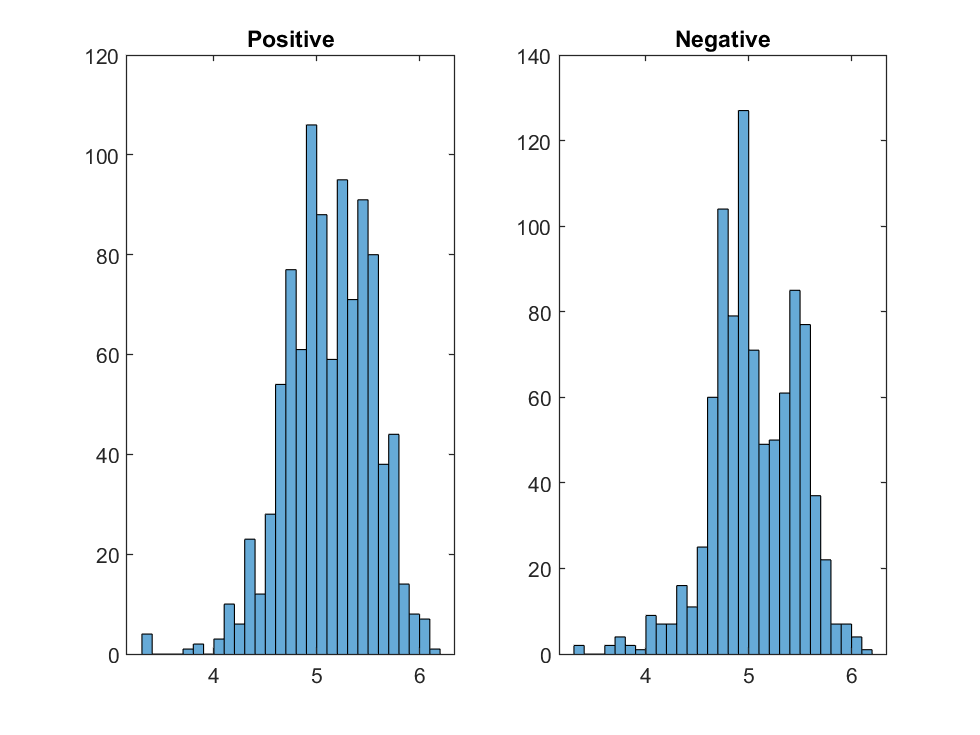

Unrecognized function or variable 'gctitle'.